# HW 2 - Matlab Exercise 2

Module 2 consists of 8 sections. loading data as we did before is where we begin

pwd

ans = '/home/speedy/repos/dsp_work/HW2_Gomez'

data = load('../HMP_Dataset/Climb_stairs/Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt')

data =      5    39    34
     2    41    34
     5    39    34
    12    38    34
     9    38    30
    10    36    29
    10    36    30
    12    36    30
    16    36    29
    16    37    30


% loading in the data from the csv matrix
data = convert(data)

data =   -12.3667    3.5000    1.1667
  -13.7667    4.4333    1.1667
  -12.3667    3.5000    1.1667
   -9.1000    3.0333    1.1667
  -10.5000    3.0333   -0.7000
  -10.0333    2.1000   -1.1667
  -10.0333    2.1000   -0.7000
   -9.1000    2.1000   -0.7000
   -7.2333    2.1000   -1.1667
   -7.2333    2.5667   -0.7000


x = data(:,1);
y = data(:,2);
z = data(:,3);

## Combining of signal

can be done with an anon function

S = @(a, b, c) (sqrt(a.^2 + b.^2 + c.^2 ))

S = function_handle with value:
    @(a,b,c)(sqrt(a.^2+b.^2+c.^2))


with this we can convert the signal for computing the energy of it.


$$E=\int_{-\infty }^{\infty } |S|^2 \textrm{dt}$$


We are in a discrete environment, so we need the following.


$$E=\sum_{-\infty }^{\infty } |S|^2$$


matlabs sum function can do this across the vector and we can pass in the squared magnitude

E = sum(mag_sigquared)

## 2 combine and calculate energy

sig_sig = S(x, y, z)'

sig_sig =    12.9053   14.5099   12.9053    9.6629   10.9518   10.3169   10.2746    9.3654    7.6218    7.7071    7.5645    7.2709    6.8387    7.6788    7.5356    8.4614    8.8881    9.0820    8.9126   10.3591   10.6493   12.5632   13.6435   15.1127   15.3699   13.0061    8.5637    8.0119    9.7972    8.7896    8.1999    7.5932    6.7101    7.1195    7.4191    7.1501    6.8387    7.8193    7.6218    8.8636    9.5951    9.0339    9.6854    9.7303   10.1036   11.1878   12.5978   15.3131   14.5997   11.4951


mag_sigquared = abs(sig_sig).^2 

mag_sigquared =   166.5456  210.5367  166.5456   93.3722  119.9411  106.4389  105.5678   87.7100   58.0922   59.3989   57.2211   52.8656   46.7678   58.9633   56.7856   71.5944   78.9989   82.4833   79.4344  107.3100  113.4078  157.8344  186.1456  228.3944  236.2344  169.1589   73.3367   64.1900   95.9856   77.2567   67.2389   57.6567   45.0256   50.6878   55.0433   51.1233   46.7678   61.1411   58.0922   78.5633   92.0656   81.6122   93.8078   94.6789  102.0833  125.1678  158.7056  234.4922  213.1500  132.1367


energy_sig = sum(mag_sigquared,"all","omitmissing","double")

energy_sig = 2.6534e+04

The energy of S is obtained.

## 3 Implementation of moving average

showing the moving average working on the data below

plot_avgs(x)

Index in position 2 is invalid. Array indices must be positive integers or logical values.

Error in hw2>plot_avgs (line 43)
plot(1:1:length(x),x,'b',2:1:length(conv_sig)-1,conv_sig(:,end-2),'r');

## Here is the convolved impulse across the signals


avg_vec = [1 1 1]./3;
hx = filter(avg_vec,1,x);
hy = filter(avg_vec,1,y);
hz = filter(avg_vec,1,z);
convX = conv(hx,x);
convY = conv(hy,y);
convZ = conv(hz,z);
reg_range = (1:1:length(hx))';
new_range = -floor(length(convX)/2):1:floor(length(convX)/2);
figure()
plot(new_range,convX,new_range,-convY,new_range,convZ)
grid on
figure()
plot(reg_range,hx,'k*',1:1:length(x),x,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with average and filter function')
legend("h_x","x","My_{avg}")
grid on

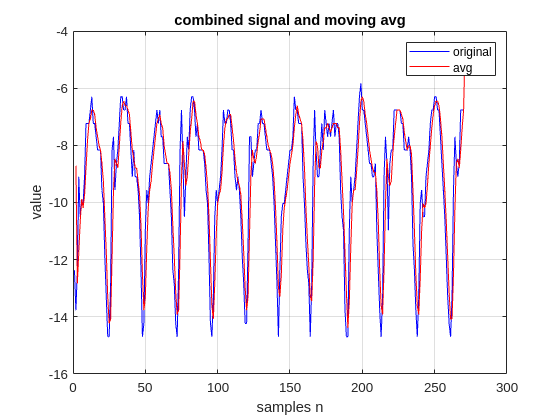

plot_avgs(x)

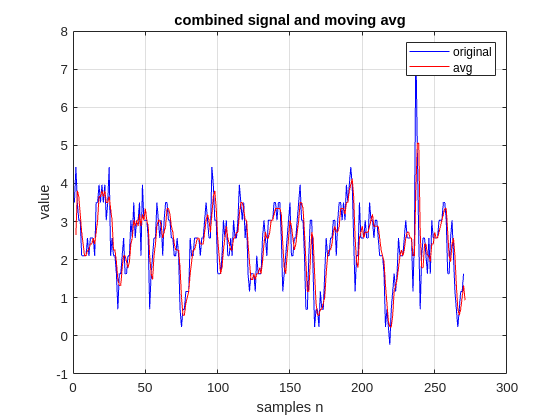

plot_avgs(y)

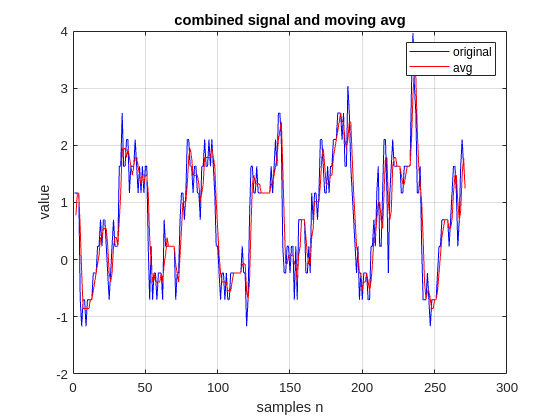

plot_avgs(z)

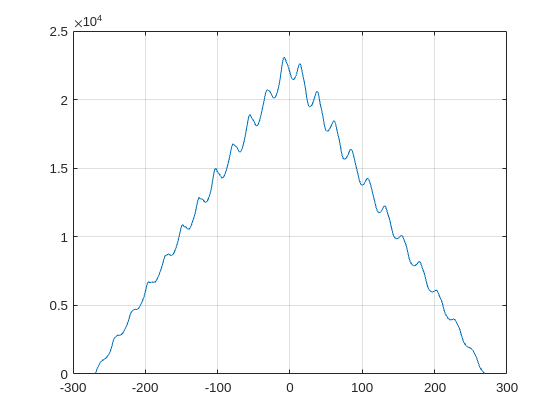

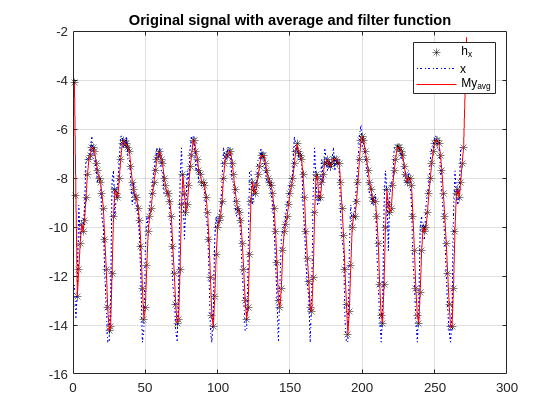


crossCorr(x)

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end

function plot_avgs(x)
avg_vec = [1 1 1]./3;
conv_sig = conv(x,avg_vec);
plot(1:1:length(x),x,'b',2:1:(length(conv_sig)-1),conv_sig(2:end-1),'r');
title('combined signal and moving avg')
xlabel('samples n')
ylabel('value')
grid on
legend('original','avg')
end

function crossCorr(x)
avg_vec = [1 1 1]./3;
conv_sig = conv(x,avg_vec);
hx = filter(avg_vec,1,x);
convX = conv(hx,x);
reg_range = (1:1:length(hx))';
new_range = -floor(length(convX)/2):1:floor(length(convX)/2);
figure()
plot(new_range,convX)
grid on
figure()
plot(reg_range,hx,'k*',1:1:length(x),x,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with average and filter function')
legend("h_x","x","My_{avg}")
grid on
end